## 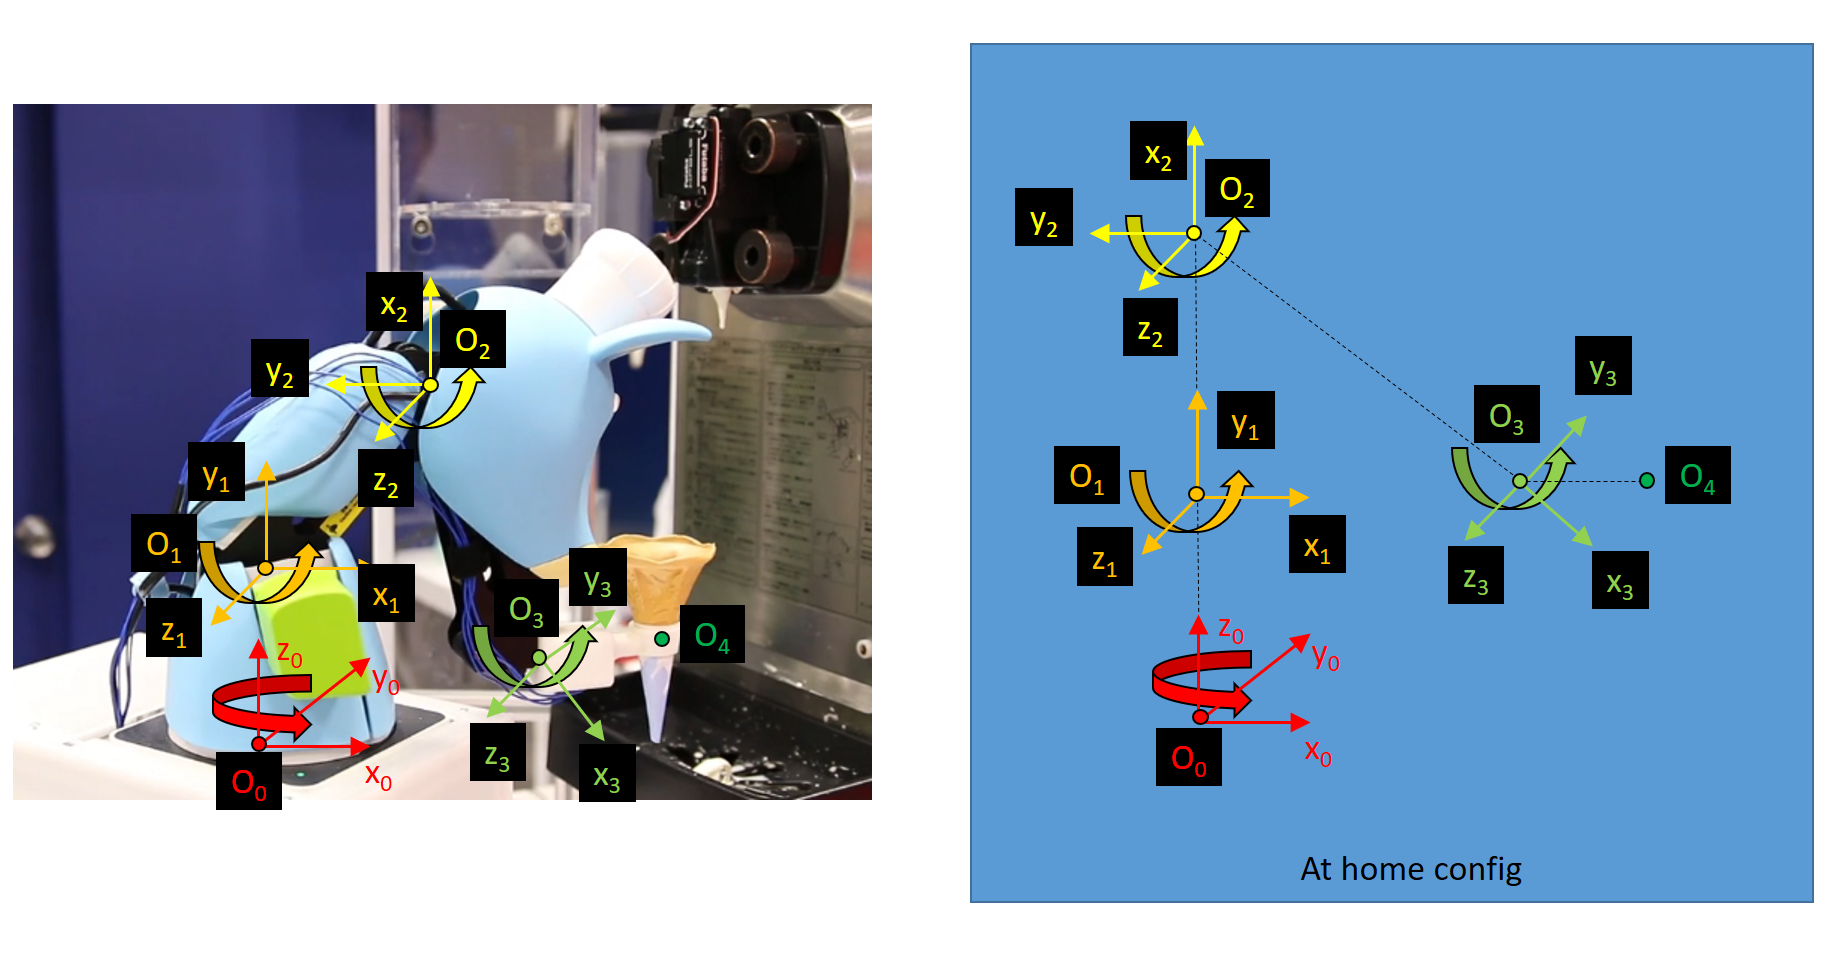

## Methods

From the DH table that we've generated for the robotic arm, we can generate the Jacobian for the arm. Once we have the Jacobian, we can determine both end effector velocities (linear and angular) as well as try to find if any singularities exist within the arm design.

The Jacobian of our arm will be a 6x4 matrix - 3 rows for each of the linear and angular velocities, and then a column for each joint on the robotic arm. Typically, the equations for the Jacobian of a given robotic joint are, for prismatic joints:


$$J_i =\left\lbrack \begin{array}{c}
z_{i-1} \\
0
\end{array}\right\rbrack$$


*Equation XX: The Jacobian for a prismatic joint*

...and for revolute joints, the Jacobian is found through:


$$J_i =\left\lbrack \begin{array}{c}
z_{i-1} x\left(o_n -o_{i-1} \right)\\
z_{i-1} 
\end{array}\right\rbrack$$


*Equation XX: The Jacobian for a revolute joint*

Our arm is a four axis robot with each joint being a revolute joint. As such, the equation for the Jacobian that we'll use is:


$$J=\left\lbrack \begin{array}{cccc}
z_0 x\left(o_4 -o_0 \right) & z_1 x\left(o_4 -o_1 \right) & z_2 x\left(o_4 -o_2 \right) & z_3 x\left(o_4 -o_3 \right)\\
z_0  & z_1  & z_2  & z_3 
\end{array}\right\rbrack$$


*Equation XX: The Jacobian for our robot arm*

When a Jacobian's determinant is equal to 0, the Jacobian is of a lower rank than the number of joints in the robot. As such, we have achieved a singularity. Unfortunately, the Jacobian for a 4 axis arm is not square, so we can not make use of the determinant of the Jacobian. We can, however, make use of two approaches that will allow us to utilize this methodolgy.

The first is that the first axis, $o_0$, acts as a rotation around the Z axis. No other joint moves along this axis, and thus the links of the robot arm can not form a singularitiy based on input from the first axis. Thus, we can ignore this axis when considering the Jacobian purely for singularities.

The other aspect that we can utilize is that the Jacobian can be decoupled. We will break the Jacobian into two square 3x3 matricies - the top matrix, $J_l$, consisting of the linear velocities and the bottom matrix, $J_a$consisting of the angular velocities. Therefore:


$$J=\left\lbrack \begin{array}{c}
J_l \\
J_a 
\end{array}\right\rbrack$$


$J_l$ and $J_a$ are square matricies, and thus our determinant heck can work. Here, if either $J_l$ or $J_a$ have a determinant of 0, we have reached a singularity.

Once we have explored the Jacobian symbollically, we will use numerical computation methods to explore the singularities for the ice cream robot arm. Many robot arms have three common sources of singularities. A **wrist singularity**, an **elbow singularity**, and an **overhead** **singularity** when the tool path crosses above the arm's head. For our applications, the overhead singularity will not be explored as our use case prevents any movement of the arm above the head.

The **wrist singularity** occurs when a wrist joint has its base frame and secondary frame - in our case $\theta_3$ and $\theta_4$ are co-linear - when $\theta_4 ==0\;\textrm{or}\;\theta_4 ==\pi$.

The **elbow singularity** occurs when the elbow's orientation matches a value based on the geometry of the robot - specifically when the angle of the elbow matches the arctan of the elbow's distance between $\theta_2$ and $\theta_3$. What that angle is we will not know until we perform numerical anaylsis of the Jacobian.

## Results

We are going to represent our Jacobian first symbollically, and then perform numerical analysis on it to find singularities.

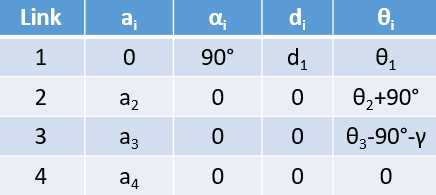delete me here for notes

syms theta1 theta2 theta3 theta4 gamma d1 a2 a3 a4

dh_table = {
             [theta1                d1      0       0],
             [theta2+(pi/2)         0       a2      0],
             [theta3-(pi/2)-gamma   0       a3      0],
             [theta4                0       a4      0],
           };

j = jacobian_from_dh_table(dh_table, true)

$$j = \begin{array}{l} \left(\begin{array}{cccc} \sigma_{1} & \sigma_{1} & -\sigma_{3}-a_{3}\,\sin\left(\theta_{1}-\gamma +\theta_{2}+\theta_{3}\right) & -\sigma_{3}\\ \sigma_{2} & \sigma_{2} & \sigma_{4}+a_{3}\,\cos\left(\theta_{1}-\gamma +\theta_{2}+\theta_{3}\right) & \sigma_{4}\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 1 & 1 & 1 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=-\sigma_{3}-a_{2}\,\cos\left(\theta_{1}+\theta_{2}\right)-a_{3}\,\sin\left(\theta_{1}-\gamma +\theta_{2}+\theta_{3}\right)\\ \sigma_{2}=\sigma_{4}-a_{2}\,\sin\left(\theta_{1}+\theta_{2}\right)+a_{3}\,\cos\left(\theta_{1}-\gamma +\theta_{2}+\theta_{3}\right)\\ \sigma_{3}=a_{4}\,\sin\left(\theta_{1}-\gamma +\theta_{2}+\theta_{3}+\theta_{4}\right)\\ \sigma_{4}=a_{4}\,\cos\left(\theta_{1}-\gamma +\theta_{2}+\theta_{3}+\theta_{4}\right) \end{array}$$

Talk about the analytical jacobian


$$\begin{array}{l}
\left(\begin{array}{cccc}
\sigma_1  & \sigma_1  & -\sigma_3 -a_3 \,\mathrm{sin}\left(\theta_1 -\gamma +\theta_2 +\theta_3 \right) & -\sigma_3 \\
\sigma_2  & \sigma_2  & \sigma_4 +a_3 \,\mathrm{cos}\left(\theta_1 -\gamma +\theta_2 +\theta_3 \right) & \sigma_4 \\
0 & 0 & 0 & 0\\
0 & 0 & 0 & 0\\
0 & 0 & 0 & 0\\
1 & 1 & 1 & 1
\end{array}\right)\\
\mathrm{}\\
\mathrm{where}\\
\mathrm{}\\
\mathrm{\ \ }\sigma_1 =-\sigma_3 -a_2 \,\mathrm{cos}\left(\theta_1 +\theta_2 \right)-a_3 \,\mathrm{sin}\left(\theta_1 -\gamma +\theta_2 +\theta_3 \right)\\
\mathrm{}\\
\mathrm{\ \ }\sigma_2 =\sigma_4 -a_2 \,\mathrm{sin}\left(\theta_1 +\theta_2 \right)+a_3 \,\mathrm{cos}\left(\theta_1 -\gamma +\theta_2 +\theta_3 \right)\\
\mathrm{}\\
\mathrm{\ \ }\sigma_3 =a_4 \,\mathrm{sin}\left(\theta_1 -\gamma +\theta_2 +\theta_3 +\theta_4 \right)\\
\mathrm{}\\
\mathrm{\ \ }\sigma_4 =a_4 \,\mathrm{cos}\left(\theta_1 -\gamma +\theta_2 +\theta_3 +\theta_4 \right)
\end{array}$$


Calculate the numerical Jacobian to find singularities:

OVERHEAD

thetas = 0:359

thetas =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49


theta1 = 23;
theta3 = 32;
theta4 = 14;
gamma = 90;
d1 = 1;
a2 = 1;
a3 = 1;
a4 = 1;
distances = zeros(1, length(thetas));
determinants = zeros(1, length(thetas));
for step = 1:length(thetas)
    theta = thetas(step)
    dh_table = {
%              [theta1                d1      0       0],
             [theta                 0       a2      0],
             [theta3-90-gamma       0       a3      0],
             [theta4                0       a4      0],
           };
    j = jacobian_from_dh_table(dh_table)
%     pinv(j)
    j_svd = svd(j)
    min(j_svd)
%     j_l = j(1:3,2:4);
%     det(j_l)
%     j_a = j(4:6,2:4);
%     det(j_a)
    determinants(step) = det(j_l) * det(j_a);
end

theta = 0

j =     1.2493    1.2493    0.7193
   -0.5427   -1.5427   -0.6947
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd =     3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 1

j =     1.2585    1.2760    0.7314
   -0.5208   -1.5207   -0.6820
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd =     3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 2

j =     1.2674    1.3023    0.7431
   -0.4988   -1.4982   -0.6691
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd =     3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 3

j =     1.2760    1.3283    0.7547
   -0.4766   -1.4752   -0.6561
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd =     3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 4

j =     1.2841    1.3538    0.7660
   -0.4542   -1.4518   -0.6428
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd =     3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 5

j =     1.2918    1.3790    0.7771
   -0.4318   -1.4280   -0.6293
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd =     3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 6

j =     1.2991    1.4037    0.7880
   -0.4092   -1.4037   -0.6157
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd =     3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 7

j =     1.3061    1.4280    0.7986
   -0.3864   -1.3790   -0.6018
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd =     3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 8

j =     1.3126    1.4518    0.8090
   -0.3636   -1.3538   -0.5878
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd =     3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 9

j =     1.3188    1.4752    0.8192
   -0.3406   -1.3283   -0.5736
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd =     3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 10

j =     1.3245    1.4982    0.8290
   -0.3175   -1.3023   -0.5592
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd =     3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 11

j =     1.3299    1.5207    0.8387
   -0.2944   -1.2760   -0.5446
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd =     3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 12

j =     1.3348    1.5427    0.8480
   -0.2711   -1.2493   -0.5299
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd =     3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 13

j =     1.3393    1.5643    0.8572
   -0.2478   -1.2221   -0.5150
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd =     3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 14

j =     1.3434    1.5854    0.8660
   -0.2244   -1.1947   -0.5000
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd =     3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 15

j =     1.3472    1.6060    0.8746
   -0.2009   -1.1668   -0.4848
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd =     3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 16

j =     1.3505    1.6261    0.8829
   -0.1773   -1.1386   -0.4695
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd =     3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 17

j =     1.3533    1.6457    0.8910
   -0.1537   -1.1100   -0.4540
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd =     3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 18

j =     1.3558    1.6648    0.8988
   -0.1301   -1.0812   -0.4384
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd =     3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 19

j =     1.3579    1.6835    0.9063
   -0.1064   -1.0519   -0.4226
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd =     3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 20

j =     1.3595    1.7016    0.9135
   -0.0827   -1.0224   -0.4067
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd =     3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 21

j =     1.3608    1.7191    0.9205
   -0.0590   -0.9925   -0.3907
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd =     3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 22

j =     1.3616    1.7362    0.9272
   -0.0352   -0.9624   -0.3746
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd =     3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 23

j =     1.3620    1.7527    0.9336
   -0.0114   -0.9319   -0.3584
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd =     3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 24

j =     1.3620    1.7687    0.9397
    0.0123   -0.9012   -0.3420
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 25

j = 6×3
    1.3616    1.7842    0.9455
    0.0361   -0.8702   -0.3256
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 26

j = 6×3
    1.3607    1.7991    0.9511
    0.0599   -0.8389   -0.3090
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 27

j = 6×3
    1.3595    1.8135    0.9563
    0.0836   -0.8074   -0.2924
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 28

j = 6×3
    1.3578    1.8273    0.9613
    0.1073   -0.7756   -0.2756
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 29

j = 6×3
    1.3557    1.8405    0.9659
    0.1310   -0.7436   -0.2588
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 30

j = 6×3
    1.3532    1.8532    0.9703
    0.1546   -0.7114   -0.2419
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 31

j = 6×3
    1.3503    1.8654    0.9744
    0.1782   -0.6789   -0.2250
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 32

j = 6×3
    1.3470    1.8769    0.9781
    0.2018   -0.6463   -0.2079
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 33

j = 6×3
    1.3433    1.8879    0.9816
    0.2252   -0.6134   -0.1908
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 34

j = 6×3
    1.3392    1.8984    0.9848
    0.2487   -0.5804   -0.1736
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 35

j = 6×3
    1.3346    1.9082    0.9877
    0.2720   -0.5472   -0.1564
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 36

j = 6×3
    1.3297    1.9175    0.9903
    0.2952   -0.5138   -0.1392
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 37

j = 6×3
    1.3243    1.9261    0.9925
    0.3184   -0.4802   -0.1219
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 38

j = 6×3
    1.3186    1.9342    0.9945
    0.3415   -0.4465   -0.1045
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 39

j = 6×3
    1.3124    1.9417    0.9962
    0.3644   -0.4127   -0.0872
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 40

j = 6×3
    1.3058    1.9486    0.9976
    0.3873   -0.3788   -0.0698
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 41

j = 6×3
    1.2989    1.9549    0.9986
    0.4100   -0.3447   -0.0523
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 42

j = 6×3
    1.2915    1.9607    0.9994
    0.4326   -0.3105   -0.0349
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 43

j = 6×3
    1.2838    1.9658    0.9998
    0.4551   -0.2763   -0.0175
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 44

j = 6×3
    1.2756    1.9703    1.0000
    0.4774   -0.2419   -0.0000
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 45

j = 6×3
    1.2671    1.9742    0.9998
    0.4996   -0.2075    0.0175
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 46

j = 6×3
    1.2582    1.9775    0.9994
    0.5216   -0.1730    0.0349
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 47

j = 6×3
    1.2489    1.9803    0.9986
    0.5435   -0.1385    0.0523
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 48

j = 6×3
    1.2392    1.9824    0.9976
    0.5652   -0.1039    0.0698
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 49

j = 6×3
    1.2292    1.9839    0.9962
    0.5868   -0.0693    0.0872
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 50

j = 6×3
    1.2187    1.9848    0.9945
    0.6081   -0.0346    0.1045
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 51

j = 6×3
    1.2079    1.9851    0.9925
    0.6293    0.0000    0.1219
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 52

j = 6×3
    1.1968    1.9848    0.9903
    0.6503    0.0346    0.1392
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 53

j = 6×3
    1.1852    1.9839    0.9877
    0.6711    0.0693    0.1564
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 54

j = 6×3
    1.1734    1.9824    0.9848
    0.6917    0.1039    0.1736
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 55

j = 6×3
    1.1611    1.9803    0.9816
    0.7120    0.1385    0.1908
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 56

j = 6×3
    1.1485    1.9775    0.9781
    0.7322    0.1730    0.2079
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 57

j = 6×3
    1.1355    1.9742    0.9744
    0.7521    0.2075    0.2250
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 58

j = 6×3
    1.1222    1.9703    0.9703
    0.7718    0.2419    0.2419
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 59

j = 6×3
    1.1086    1.9658    0.9659
    0.7913    0.2763    0.2588
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 60

j = 6×3
    1.0946    1.9607    0.9613
    0.8105    0.3105    0.2756
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 61

j = 6×3
    1.0803    1.9549    0.9563
    0.8295    0.3447    0.2924
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 62

j = 6×3
    1.0657    1.9486    0.9511
    0.8482    0.3788    0.3090
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 63

j = 6×3
    1.0507    1.9417    0.9455
    0.8667    0.4127    0.3256
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 64

j = 6×3
    1.0354    1.9342    0.9397
    0.8849    0.4465    0.3420
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 65

j = 6×3
    1.0198    1.9261    0.9336
    0.9029    0.4802    0.3584
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 66

j = 6×3
    1.0039    1.9175    0.9272
    0.9205    0.5138    0.3746
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 67

j = 6×3
    0.9877    1.9082    0.9205
    0.9379    0.5472    0.3907
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 68

j = 6×3
    0.9712    1.8984    0.9135
    0.9550    0.5804    0.4067
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 69

j = 6×3
    0.9544    1.8879    0.9063
    0.9718    0.6134    0.4226
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 70

j = 6×3
    0.9372    1.8769    0.8988
    0.9883    0.6463    0.4384
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 71

j = 6×3
    0.9199    1.8654    0.8910
    1.0045    0.6789    0.4540
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 72

j = 6×3
    0.9022    1.8532    0.8829
    1.0204    0.7114    0.4695
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 73

j = 6×3
    0.8842    1.8405    0.8746
    1.0360    0.7436    0.4848
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 74

j = 6×3
    0.8660    1.8273    0.8660
    1.0513    0.7756    0.5000
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 75

j = 6×3
    0.8475    1.8135    0.8572
    1.0662    0.8074    0.5150
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 76

j = 6×3
    0.8288    1.7991    0.8480
    1.0809    0.8389    0.5299
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 77

j = 6×3
    0.8098    1.7842    0.8387
    1.0952    0.8702    0.5446
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 78

j = 6×3
    0.7906    1.7687    0.8290
    1.1091    0.9012    0.5592
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 79

j = 6×3
    0.7711    1.7527    0.8192
    1.1228    0.9319    0.5736
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 80

j = 6×3
    0.7514    1.7362    0.8090
    1.1360    0.9624    0.5878
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 81

j = 6×3
    0.7315    1.7191    0.7986
    1.1490    0.9925    0.6018
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 82

j = 6×3
    0.7113    1.7016    0.7880
    1.1616    1.0224    0.6157
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 83

j = 6×3
    0.6909    1.6835    0.7771
    1.1738    1.0519    0.6293
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 84

j = 6×3
    0.6703    1.6648    0.7660
    1.1857    1.0812    0.6428
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 85

j = 6×3
    0.6495    1.6457    0.7547
    1.1972    1.1100    0.6561
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 86

j = 6×3
    0.6285    1.6261    0.7431
    1.2084    1.1386    0.6691
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 87

j = 6×3
    0.6073    1.6060    0.7314
    1.2191    1.1668    0.6820
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 88

j = 6×3
    0.5860    1.5854    0.7193
    1.2296    1.1947    0.6947
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 89

j = 6×3
    0.5644    1.5643    0.7071
    1.2396    1.2221    0.7071
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 90

j = 6×3
    0.5427    1.5427    0.6947
    1.2493    1.2493    0.7193
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 91

j = 6×3
    0.5208    1.5207    0.6820
    1.2585    1.2760    0.7314
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 92

j = 6×3
    0.4988    1.4982    0.6691
    1.2674    1.3023    0.7431
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 93

j = 6×3
    0.4766    1.4752    0.6561
    1.2760    1.3283    0.7547
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 94

j = 6×3
    0.4542    1.4518    0.6428
    1.2841    1.3538    0.7660
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 95

j = 6×3
    0.4318    1.4280    0.6293
    1.2918    1.3790    0.7771
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 96

j = 6×3
    0.4092    1.4037    0.6157
    1.2991    1.4037    0.7880
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 97

j = 6×3
    0.3864    1.3790    0.6018
    1.3061    1.4280    0.7986
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 98

j = 6×3
    0.3636    1.3538    0.5878
    1.3126    1.4518    0.8090
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 99

j = 6×3
    0.3406    1.3283    0.5736
    1.3188    1.4752    0.8192
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 100

j = 6×3
    0.3175    1.3023    0.5592
    1.3245    1.4982    0.8290
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 101

j = 6×3
    0.2944    1.2760    0.5446
    1.3299    1.5207    0.8387
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 102

j = 6×3
    0.2711    1.2493    0.5299
    1.3348    1.5427    0.8480
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 103

j = 6×3
    0.2478    1.2221    0.5150
    1.3393    1.5643    0.8572
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 104

j = 6×3
    0.2244    1.1947    0.5000
    1.3434    1.5854    0.8660
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 105

j = 6×3
    0.2009    1.1668    0.4848
    1.3472    1.6060    0.8746
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 106

j = 6×3
    0.1773    1.1386    0.4695
    1.3505    1.6261    0.8829
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 107

j = 6×3
    0.1537    1.1100    0.4540
    1.3533    1.6457    0.8910
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 108

j = 6×3
    0.1301    1.0812    0.4384
    1.3558    1.6648    0.8988
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 109

j = 6×3
    0.1064    1.0519    0.4226
    1.3579    1.6835    0.9063
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 110

j = 6×3
    0.0827    1.0224    0.4067
    1.3595    1.7016    0.9135
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 111

j = 6×3
    0.0590    0.9925    0.3907
    1.3608    1.7191    0.9205
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 112

j = 6×3
    0.0352    0.9624    0.3746
    1.3616    1.7362    0.9272
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 113

j = 6×3
    0.0114    0.9319    0.3584
    1.3620    1.7527    0.9336
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 114

j = 6×3
   -0.0123    0.9012    0.3420
    1.3620    1.7687    0.9397
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 115

j = 6×3
   -0.0361    0.8702    0.3256
    1.3616    1.7842    0.9455
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 116

j = 6×3
   -0.0599    0.8389    0.3090
    1.3607    1.7991    0.9511
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 117

j = 6×3
   -0.0836    0.8074    0.2924
    1.3595    1.8135    0.9563
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 118

j = 6×3
   -0.1073    0.7756    0.2756
    1.3578    1.8273    0.9613
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 119

j = 6×3
   -0.1310    0.7436    0.2588
    1.3557    1.8405    0.9659
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 120

j = 6×3
   -0.1546    0.7114    0.2419
    1.3532    1.8532    0.9703
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 121

j = 6×3
   -0.1782    0.6789    0.2250
    1.3503    1.8654    0.9744
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 122

j = 6×3
   -0.2018    0.6463    0.2079
    1.3470    1.8769    0.9781
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 123

j = 6×3
   -0.2252    0.6134    0.1908
    1.3433    1.8879    0.9816
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 124

j = 6×3
   -0.2487    0.5804    0.1736
    1.3392    1.8984    0.9848
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 125

j = 6×3
   -0.2720    0.5472    0.1564
    1.3346    1.9082    0.9877
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 126

j = 6×3
   -0.2952    0.5138    0.1392
    1.3297    1.9175    0.9903
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 127

j = 6×3
   -0.3184    0.4802    0.1219
    1.3243    1.9261    0.9925
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 128

j = 6×3
   -0.3415    0.4465    0.1045
    1.3186    1.9342    0.9945
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 129

j = 6×3
   -0.3644    0.4127    0.0872
    1.3124    1.9417    0.9962
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 130

j = 6×3
   -0.3873    0.3788    0.0698
    1.3058    1.9486    0.9976
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 131

j = 6×3
   -0.4100    0.3447    0.0523
    1.2989    1.9549    0.9986
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 132

j = 6×3
   -0.4326    0.3105    0.0349
    1.2915    1.9607    0.9994
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 133

j = 6×3
   -0.4551    0.2763    0.0175
    1.2838    1.9658    0.9998
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 134

j = 6×3
   -0.4774    0.2419    0.0000
    1.2756    1.9703    1.0000
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 135

j = 6×3
   -0.4996    0.2075   -0.0175
    1.2671    1.9742    0.9998
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 136

j = 6×3
   -0.5216    0.1730   -0.0349
    1.2582    1.9775    0.9994
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 137

j = 6×3
   -0.5435    0.1385   -0.0523
    1.2489    1.9803    0.9986
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 138

j = 6×3
   -0.5652    0.1039   -0.0698
    1.2392    1.9824    0.9976
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 139

j = 6×3
   -0.5868    0.0693   -0.0872
    1.2292    1.9839    0.9962
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 140

j = 6×3
   -0.6081    0.0346   -0.1045
    1.2187    1.9848    0.9945
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 141

j = 6×3
   -0.6293   -0.0000   -0.1219
    1.2079    1.9851    0.9925
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 142

j = 6×3
   -0.6503   -0.0346   -0.1392
    1.1968    1.9848    0.9903
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 143

j = 6×3
   -0.6711   -0.0693   -0.1564
    1.1852    1.9839    0.9877
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 144

j = 6×3
   -0.6917   -0.1039   -0.1736
    1.1734    1.9824    0.9848
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 145

j = 6×3
   -0.7120   -0.1385   -0.1908
    1.1611    1.9803    0.9816
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 146

j = 6×3
   -0.7322   -0.1730   -0.2079
    1.1485    1.9775    0.9781
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 147

j = 6×3
   -0.7521   -0.2075   -0.2250
    1.1355    1.9742    0.9744
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 148

j = 6×3
   -0.7718   -0.2419   -0.2419
    1.1222    1.9703    0.9703
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 149

j = 6×3
   -0.7913   -0.2763   -0.2588
    1.1086    1.9658    0.9659
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 150

j = 6×3
   -0.8105   -0.3105   -0.2756
    1.0946    1.9607    0.9613
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 151

j = 6×3
   -0.8295   -0.3447   -0.2924
    1.0803    1.9549    0.9563
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 152

j = 6×3
   -0.8482   -0.3788   -0.3090
    1.0657    1.9486    0.9511
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 153

j = 6×3
   -0.8667   -0.4127   -0.3256
    1.0507    1.9417    0.9455
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 154

j = 6×3
   -0.8849   -0.4465   -0.3420
    1.0354    1.9342    0.9397
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 155

j = 6×3
   -0.9029   -0.4802   -0.3584
    1.0198    1.9261    0.9336
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 156

j = 6×3
   -0.9205   -0.5138   -0.3746
    1.0039    1.9175    0.9272
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 157

j = 6×3
   -0.9379   -0.5472   -0.3907
    0.9877    1.9082    0.9205
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 158

j = 6×3
   -0.9550   -0.5804   -0.4067
    0.9712    1.8984    0.9135
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 159

j = 6×3
   -0.9718   -0.6134   -0.4226
    0.9544    1.8879    0.9063
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 160

j = 6×3
   -0.9883   -0.6463   -0.4384
    0.9372    1.8769    0.8988
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 161

j = 6×3
   -1.0045   -0.6789   -0.4540
    0.9199    1.8654    0.8910
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 162

j = 6×3
   -1.0204   -0.7114   -0.4695
    0.9022    1.8532    0.8829
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 163

j = 6×3
   -1.0360   -0.7436   -0.4848
    0.8842    1.8405    0.8746
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 164

j = 6×3
   -1.0513   -0.7756   -0.5000
    0.8660    1.8273    0.8660
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 165

j = 6×3
   -1.0662   -0.8074   -0.5150
    0.8475    1.8135    0.8572
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 166

j = 6×3
   -1.0809   -0.8389   -0.5299
    0.8288    1.7991    0.8480
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 167

j = 6×3
   -1.0952   -0.8702   -0.5446
    0.8098    1.7842    0.8387
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 168

j = 6×3
   -1.1091   -0.9012   -0.5592
    0.7906    1.7687    0.8290
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 169

j = 6×3
   -1.1228   -0.9319   -0.5736
    0.7711    1.7527    0.8192
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 170

j = 6×3
   -1.1360   -0.9624   -0.5878
    0.7514    1.7362    0.8090
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 171

j = 6×3
   -1.1490   -0.9925   -0.6018
    0.7315    1.7191    0.7986
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 172

j = 6×3
   -1.1616   -1.0224   -0.6157
    0.7113    1.7016    0.7880
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 173

j = 6×3
   -1.1738   -1.0519   -0.6293
    0.6909    1.6835    0.7771
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 174

j = 6×3
   -1.1857   -1.0812   -0.6428
    0.6703    1.6648    0.7660
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 175

j = 6×3
   -1.1972   -1.1100   -0.6561
    0.6495    1.6457    0.7547
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 176

j = 6×3
   -1.2084   -1.1386   -0.6691
    0.6285    1.6261    0.7431
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 177

j = 6×3
   -1.2191   -1.1668   -0.6820
    0.6073    1.6060    0.7314
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 178

j = 6×3
   -1.2296   -1.1947   -0.6947
    0.5860    1.5854    0.7193
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 179

j = 6×3
   -1.2396   -1.2221   -0.7071
    0.5644    1.5643    0.7071
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 180

j = 6×3
   -1.2493   -1.2493   -0.7193
    0.5427    1.5427    0.6947
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 181

j = 6×3
   -1.2585   -1.2760   -0.7314
    0.5208    1.5207    0.6820
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 182

j = 6×3
   -1.2674   -1.3023   -0.7431
    0.4988    1.4982    0.6691
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 183

j = 6×3
   -1.2760   -1.3283   -0.7547
    0.4766    1.4752    0.6561
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 184

j = 6×3
   -1.2841   -1.3538   -0.7660
    0.4542    1.4518    0.6428
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 185

j = 6×3
   -1.2918   -1.3790   -0.7771
    0.4318    1.4280    0.6293
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 186

j = 6×3
   -1.2991   -1.4037   -0.7880
    0.4092    1.4037    0.6157
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 187

j = 6×3
   -1.3061   -1.4280   -0.7986
    0.3864    1.3790    0.6018
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 188

j = 6×3
   -1.3126   -1.4518   -0.8090
    0.3636    1.3538    0.5878
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 189

j = 6×3
   -1.3188   -1.4752   -0.8192
    0.3406    1.3283    0.5736
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 190

j = 6×3
   -1.3245   -1.4982   -0.8290
    0.3175    1.3023    0.5592
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 191

j = 6×3
   -1.3299   -1.5207   -0.8387
    0.2944    1.2760    0.5446
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 192

j = 6×3
   -1.3348   -1.5427   -0.8480
    0.2711    1.2493    0.5299
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 193

j = 6×3
   -1.3393   -1.5643   -0.8572
    0.2478    1.2221    0.5150
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 194

j = 6×3
   -1.3434   -1.5854   -0.8660
    0.2244    1.1947    0.5000
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 195

j = 6×3
   -1.3472   -1.6060   -0.8746
    0.2009    1.1668    0.4848
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 196

j = 6×3
   -1.3505   -1.6261   -0.8829
    0.1773    1.1386    0.4695
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 197

j = 6×3
   -1.3533   -1.6457   -0.8910
    0.1537    1.1100    0.4540
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 198

j = 6×3
   -1.3558   -1.6648   -0.8988
    0.1301    1.0812    0.4384
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 199

j = 6×3
   -1.3579   -1.6835   -0.9063
    0.1064    1.0519    0.4226
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 200

j = 6×3
   -1.3595   -1.7016   -0.9135
    0.0827    1.0224    0.4067
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 201

j = 6×3
   -1.3608   -1.7191   -0.9205
    0.0590    0.9925    0.3907
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 202

j = 6×3
   -1.3616   -1.7362   -0.9272
    0.0352    0.9624    0.3746
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 203

j = 6×3
   -1.3620   -1.7527   -0.9336
    0.0114    0.9319    0.3584
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 204

j = 6×3
   -1.3620   -1.7687   -0.9397
   -0.0123    0.9012    0.3420
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 205

j = 6×3
   -1.3616   -1.7842   -0.9455
   -0.0361    0.8702    0.3256
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 206

j = 6×3
   -1.3607   -1.7991   -0.9511
   -0.0599    0.8389    0.3090
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 207

j = 6×3
   -1.3595   -1.8135   -0.9563
   -0.0836    0.8074    0.2924
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 208

j = 6×3
   -1.3578   -1.8273   -0.9613
   -0.1073    0.7756    0.2756
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 209

j = 6×3
   -1.3557   -1.8405   -0.9659
   -0.1310    0.7436    0.2588
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 210

j = 6×3
   -1.3532   -1.8532   -0.9703
   -0.1546    0.7114    0.2419
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 211

j = 6×3
   -1.3503   -1.8654   -0.9744
   -0.1782    0.6789    0.2250
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 212

j = 6×3
   -1.3470   -1.8769   -0.9781
   -0.2018    0.6463    0.2079
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 213

j = 6×3
   -1.3433   -1.8879   -0.9816
   -0.2252    0.6134    0.1908
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 214

j = 6×3
   -1.3392   -1.8984   -0.9848
   -0.2487    0.5804    0.1736
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 215

j = 6×3
   -1.3346   -1.9082   -0.9877
   -0.2720    0.5472    0.1564
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 216

j = 6×3
   -1.3297   -1.9175   -0.9903
   -0.2952    0.5138    0.1392
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 217

j = 6×3
   -1.3243   -1.9261   -0.9925
   -0.3184    0.4802    0.1219
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 218

j = 6×3
   -1.3186   -1.9342   -0.9945
   -0.3415    0.4465    0.1045
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 219

j = 6×3
   -1.3124   -1.9417   -0.9962
   -0.3644    0.4127    0.0872
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 220

j = 6×3
   -1.3058   -1.9486   -0.9976
   -0.3873    0.3788    0.0698
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 221

j = 6×3
   -1.2989   -1.9549   -0.9986
   -0.4100    0.3447    0.0523
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 222

j = 6×3
   -1.2915   -1.9607   -0.9994
   -0.4326    0.3105    0.0349
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 223

j = 6×3
   -1.2838   -1.9658   -0.9998
   -0.4551    0.2763    0.0175
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 224

j = 6×3
   -1.2756   -1.9703   -1.0000
   -0.4774    0.2419    0.0000
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 225

j = 6×3
   -1.2671   -1.9742   -0.9998
   -0.4996    0.2075   -0.0175
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 226

j = 6×3
   -1.2582   -1.9775   -0.9994
   -0.5216    0.1730   -0.0349
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 227

j = 6×3
   -1.2489   -1.9803   -0.9986
   -0.5435    0.1385   -0.0523
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 228

j = 6×3
   -1.2392   -1.9824   -0.9976
   -0.5652    0.1039   -0.0698
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 229

j = 6×3
   -1.2292   -1.9839   -0.9962
   -0.5868    0.0693   -0.0872
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 230

j = 6×3
   -1.2187   -1.9848   -0.9945
   -0.6081    0.0346   -0.1045
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 231

j = 6×3
   -1.2079   -1.9851   -0.9925
   -0.6293   -0.0000   -0.1219
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 232

j = 6×3
   -1.1968   -1.9848   -0.9903
   -0.6503   -0.0346   -0.1392
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 233

j = 6×3
   -1.1852   -1.9839   -0.9877
   -0.6711   -0.0693   -0.1564
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 234

j = 6×3
   -1.1734   -1.9824   -0.9848
   -0.6917   -0.1039   -0.1736
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 235

j = 6×3
   -1.1611   -1.9803   -0.9816
   -0.7120   -0.1385   -0.1908
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 236

j = 6×3
   -1.1485   -1.9775   -0.9781
   -0.7322   -0.1730   -0.2079
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 237

j = 6×3
   -1.1355   -1.9742   -0.9744
   -0.7521   -0.2075   -0.2250
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 238

j = 6×3
   -1.1222   -1.9703   -0.9703
   -0.7718   -0.2419   -0.2419
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 239

j = 6×3
   -1.1086   -1.9658   -0.9659
   -0.7913   -0.2763   -0.2588
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 240

j = 6×3
   -1.0946   -1.9607   -0.9613
   -0.8105   -0.3105   -0.2756
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 241

j = 6×3
   -1.0803   -1.9549   -0.9563
   -0.8295   -0.3447   -0.2924
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 242

j = 6×3
   -1.0657   -1.9486   -0.9511
   -0.8482   -0.3788   -0.3090
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 243

j = 6×3
   -1.0507   -1.9417   -0.9455
   -0.8667   -0.4127   -0.3256
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 244

j = 6×3
   -1.0354   -1.9342   -0.9397
   -0.8849   -0.4465   -0.3420
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 245

j = 6×3
   -1.0198   -1.9261   -0.9336
   -0.9029   -0.4802   -0.3584
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 246

j = 6×3
   -1.0039   -1.9175   -0.9272
   -0.9205   -0.5138   -0.3746
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 247

j = 6×3
   -0.9877   -1.9082   -0.9205
   -0.9379   -0.5472   -0.3907
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 248

j = 6×3
   -0.9712   -1.8984   -0.9135
   -0.9550   -0.5804   -0.4067
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 249

j = 6×3
   -0.9544   -1.8879   -0.9063
   -0.9718   -0.6134   -0.4226
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 250

j = 6×3
   -0.9372   -1.8769   -0.8988
   -0.9883   -0.6463   -0.4384
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 251

j = 6×3
   -0.9199   -1.8654   -0.8910
   -1.0045   -0.6789   -0.4540
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 252

j = 6×3
   -0.9022   -1.8532   -0.8829
   -1.0204   -0.7114   -0.4695
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 253

j = 6×3
   -0.8842   -1.8405   -0.8746
   -1.0360   -0.7436   -0.4848
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 254

j = 6×3
   -0.8660   -1.8273   -0.8660
   -1.0513   -0.7756   -0.5000
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 255

j = 6×3
   -0.8475   -1.8135   -0.8572
   -1.0662   -0.8074   -0.5150
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 256

j = 6×3
   -0.8288   -1.7991   -0.8480
   -1.0809   -0.8389   -0.5299
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 257

j = 6×3
   -0.8098   -1.7842   -0.8387
   -1.0952   -0.8702   -0.5446
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 258

j = 6×3
   -0.7906   -1.7687   -0.8290
   -1.1091   -0.9012   -0.5592
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 259

j = 6×3
   -0.7711   -1.7527   -0.8192
   -1.1228   -0.9319   -0.5736
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 260

j = 6×3
   -0.7514   -1.7362   -0.8090
   -1.1360   -0.9624   -0.5878
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 261

j = 6×3
   -0.7315   -1.7191   -0.7986
   -1.1490   -0.9925   -0.6018
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 262

j = 6×3
   -0.7113   -1.7016   -0.7880
   -1.1616   -1.0224   -0.6157
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 263

j = 6×3
   -0.6909   -1.6835   -0.7771
   -1.1738   -1.0519   -0.6293
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 264

j = 6×3
   -0.6703   -1.6648   -0.7660
   -1.1857   -1.0812   -0.6428
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 265

j = 6×3
   -0.6495   -1.6457   -0.7547
   -1.1972   -1.1100   -0.6561
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 266

j = 6×3
   -0.6285   -1.6261   -0.7431
   -1.2084   -1.1386   -0.6691
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 267

j = 6×3
   -0.6073   -1.6060   -0.7314
   -1.2191   -1.1668   -0.6820
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 268

j = 6×3
   -0.5860   -1.5854   -0.7193
   -1.2296   -1.1947   -0.6947
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 269

j = 6×3
   -0.5644   -1.5643   -0.7071
   -1.2396   -1.2221   -0.7071
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 270

j = 6×3
   -0.5427   -1.5427   -0.6947
   -1.2493   -1.2493   -0.7193
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 271

j = 6×3
   -0.5208   -1.5207   -0.6820
   -1.2585   -1.2760   -0.7314
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 272

j = 6×3
   -0.4988   -1.4982   -0.6691
   -1.2674   -1.3023   -0.7431
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 273

j = 6×3
   -0.4766   -1.4752   -0.6561
   -1.2760   -1.3283   -0.7547
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 274

j = 6×3
   -0.4542   -1.4518   -0.6428
   -1.2841   -1.3538   -0.7660
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 275

j = 6×3
   -0.4318   -1.4280   -0.6293
   -1.2918   -1.3790   -0.7771
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 276

j = 6×3
   -0.4092   -1.4037   -0.6157
   -1.2991   -1.4037   -0.7880
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 277

j = 6×3
   -0.3864   -1.3790   -0.6018
   -1.3061   -1.4280   -0.7986
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 278

j = 6×3
   -0.3636   -1.3538   -0.5878
   -1.3126   -1.4518   -0.8090
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 279

j = 6×3
   -0.3406   -1.3283   -0.5736
   -1.3188   -1.4752   -0.8192
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 280

j = 6×3
   -0.3175   -1.3023   -0.5592
   -1.3245   -1.4982   -0.8290
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 281

j = 6×3
   -0.2944   -1.2760   -0.5446
   -1.3299   -1.5207   -0.8387
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 282

j = 6×3
   -0.2711   -1.2493   -0.5299
   -1.3348   -1.5427   -0.8480
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 283

j = 6×3
   -0.2478   -1.2221   -0.5150
   -1.3393   -1.5643   -0.8572
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 284

j = 6×3
   -0.2244   -1.1947   -0.5000
   -1.3434   -1.5854   -0.8660
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 285

j = 6×3
   -0.2009   -1.1668   -0.4848
   -1.3472   -1.6060   -0.8746
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 286

j = 6×3
   -0.1773   -1.1386   -0.4695
   -1.3505   -1.6261   -0.8829
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 287

j = 6×3
   -0.1537   -1.1100   -0.4540
   -1.3533   -1.6457   -0.8910
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 288

j = 6×3
   -0.1301   -1.0812   -0.4384
   -1.3558   -1.6648   -0.8988
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 289

j = 6×3
   -0.1064   -1.0519   -0.4226
   -1.3579   -1.6835   -0.9063
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 290

j = 6×3
   -0.0827   -1.0224   -0.4067
   -1.3595   -1.7016   -0.9135
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 291

j = 6×3
   -0.0590   -0.9925   -0.3907
   -1.3608   -1.7191   -0.9205
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 292

j = 6×3
   -0.0352   -0.9624   -0.3746
   -1.3616   -1.7362   -0.9272
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 293

j = 6×3
   -0.0114   -0.9319   -0.3584
   -1.3620   -1.7527   -0.9336
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 294

j = 6×3
    0.0123   -0.9012   -0.3420
   -1.3620   -1.7687   -0.9397
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 295

j = 6×3
    0.0361   -0.8702   -0.3256
   -1.3616   -1.7842   -0.9455
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 296

j = 6×3
    0.0599   -0.8389   -0.3090
   -1.3607   -1.7991   -0.9511
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 297

j = 6×3
    0.0836   -0.8074   -0.2924
   -1.3595   -1.8135   -0.9563
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 298

j = 6×3
    0.1073   -0.7756   -0.2756
   -1.3578   -1.8273   -0.9613
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 299

j = 6×3
    0.1310   -0.7436   -0.2588
   -1.3557   -1.8405   -0.9659
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 300

j = 6×3
    0.1546   -0.7114   -0.2419
   -1.3532   -1.8532   -0.9703
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 301

j = 6×3
    0.1782   -0.6789   -0.2250
   -1.3503   -1.8654   -0.9744
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 302

j = 6×3
    0.2018   -0.6463   -0.2079
   -1.3470   -1.8769   -0.9781
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 303

j = 6×3
    0.2252   -0.6134   -0.1908
   -1.3433   -1.8879   -0.9816
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 304

j = 6×3
    0.2487   -0.5804   -0.1736
   -1.3392   -1.8984   -0.9848
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 305

j = 6×3
    0.2720   -0.5472   -0.1564
   -1.3346   -1.9082   -0.9877
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 306

j = 6×3
    0.2952   -0.5138   -0.1392
   -1.3297   -1.9175   -0.9903
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 307

j = 6×3
    0.3184   -0.4802   -0.1219
   -1.3243   -1.9261   -0.9925
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 308

j = 6×3
    0.3415   -0.4465   -0.1045
   -1.3186   -1.9342   -0.9945
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 309

j = 6×3
    0.3644   -0.4127   -0.0872
   -1.3124   -1.9417   -0.9962
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 310

j = 6×3
    0.3873   -0.3788   -0.0698
   -1.3058   -1.9486   -0.9976
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 311

j = 6×3
    0.4100   -0.3447   -0.0523
   -1.2989   -1.9549   -0.9986
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 312

j = 6×3
    0.4326   -0.3105   -0.0349
   -1.2915   -1.9607   -0.9994
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 313

j = 6×3
    0.4551   -0.2763   -0.0175
   -1.2838   -1.9658   -0.9998
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 314

j = 6×3
    0.4774   -0.2419   -0.0000
   -1.2756   -1.9703   -1.0000
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 315

j = 6×3
    0.4996   -0.2075    0.0175
   -1.2671   -1.9742   -0.9998
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 316

j = 6×3
    0.5216   -0.1730    0.0349
   -1.2582   -1.9775   -0.9994
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 317

j = 6×3
    0.5435   -0.1385    0.0523
   -1.2489   -1.9803   -0.9986
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 318

j = 6×3
    0.5652   -0.1039    0.0698
   -1.2392   -1.9824   -0.9976
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 319

j = 6×3
    0.5868   -0.0693    0.0872
   -1.2292   -1.9839   -0.9962
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 320

j = 6×3
    0.6081   -0.0346    0.1045
   -1.2187   -1.9848   -0.9945
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 321

j = 6×3
    0.6293    0.0000    0.1219
   -1.2079   -1.9851   -0.9925
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 322

j = 6×3
    0.6503    0.0346    0.1392
   -1.1968   -1.9848   -0.9903
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 323

j = 6×3
    0.6711    0.0693    0.1564
   -1.1852   -1.9839   -0.9877
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 324

j = 6×3
    0.6917    0.1039    0.1736
   -1.1734   -1.9824   -0.9848
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 325

j = 6×3
    0.7120    0.1385    0.1908
   -1.1611   -1.9803   -0.9816
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 326

j = 6×3
    0.7322    0.1730    0.2079
   -1.1485   -1.9775   -0.9781
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 327

j = 6×3
    0.7521    0.2075    0.2250
   -1.1355   -1.9742   -0.9744
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 328

j = 6×3
    0.7718    0.2419    0.2419
   -1.1222   -1.9703   -0.9703
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 329

j = 6×3
    0.7913    0.2763    0.2588
   -1.1086   -1.9658   -0.9659
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 330

j = 6×3
    0.8105    0.3105    0.2756
   -1.0946   -1.9607   -0.9613
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 331

j = 6×3
    0.8295    0.3447    0.2924
   -1.0803   -1.9549   -0.9563
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 332

j = 6×3
    0.8482    0.3788    0.3090
   -1.0657   -1.9486   -0.9511
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 333

j = 6×3
    0.8667    0.4127    0.3256
   -1.0507   -1.9417   -0.9455
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 334

j = 6×3
    0.8849    0.4465    0.3420
   -1.0354   -1.9342   -0.9397
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 335

j = 6×3
    0.9029    0.4802    0.3584
   -1.0198   -1.9261   -0.9336
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 336

j = 6×3
    0.9205    0.5138    0.3746
   -1.0039   -1.9175   -0.9272
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 337

j = 6×3
    0.9379    0.5472    0.3907
   -0.9877   -1.9082   -0.9205
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 338

j = 6×3
    0.9550    0.5804    0.4067
   -0.9712   -1.8984   -0.9135
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 339

j = 6×3
    0.9718    0.6134    0.4226
   -0.9544   -1.8879   -0.9063
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 340

j = 6×3
    0.9883    0.6463    0.4384
   -0.9372   -1.8769   -0.8988
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 341

j = 6×3
    1.0045    0.6789    0.4540
   -0.9199   -1.8654   -0.8910
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 342

j = 6×3
    1.0204    0.7114    0.4695
   -0.9022   -1.8532   -0.8829
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 343

j = 6×3
    1.0360    0.7436    0.4848
   -0.8842   -1.8405   -0.8746
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 344

j = 6×3
    1.0513    0.7756    0.5000
   -0.8660   -1.8273   -0.8660
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 345

j = 6×3
    1.0662    0.8074    0.5150
   -0.8475   -1.8135   -0.8572
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 346

j = 6×3
    1.0809    0.8389    0.5299
   -0.8288   -1.7991   -0.8480
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 347

j = 6×3
    1.0952    0.8702    0.5446
   -0.8098   -1.7842   -0.8387
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 348

j = 6×3
    1.1091    0.9012    0.5592
   -0.7906   -1.7687   -0.8290
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 349

j = 6×3
    1.1228    0.9319    0.5736
   -0.7711   -1.7527   -0.8192
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 350

j = 6×3
    1.1360    0.9624    0.5878
   -0.7514   -1.7362   -0.8090
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 351

j = 6×3
    1.1490    0.9925    0.6018
   -0.7315   -1.7191   -0.7986
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 352

j = 6×3
    1.1616    1.0224    0.6157
   -0.7113   -1.7016   -0.7880
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 353

j = 6×3
    1.1738    1.0519    0.6293
   -0.6909   -1.6835   -0.7771
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 354

j = 6×3
    1.1857    1.0812    0.6428
   -0.6703   -1.6648   -0.7660
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 355

j = 6×3
    1.1972    1.1100    0.6561
   -0.6495   -1.6457   -0.7547
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 356

j = 6×3
    1.2084    1.1386    0.6691
   -0.6285   -1.6261   -0.7431
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 357

j = 6×3
    1.2191    1.1668    0.6820
   -0.6073   -1.6060   -0.7314
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 358

j = 6×3
    1.2296    1.1947    0.6947
   -0.5860   -1.5854   -0.7193
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

theta = 359

j = 6×3
    1.2396    1.2221    0.7071
   -0.5644   -1.5643   -0.7071
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


j_svd = 3×1
    3.0586
    0.5969
    0.2903


ans = 0.2903

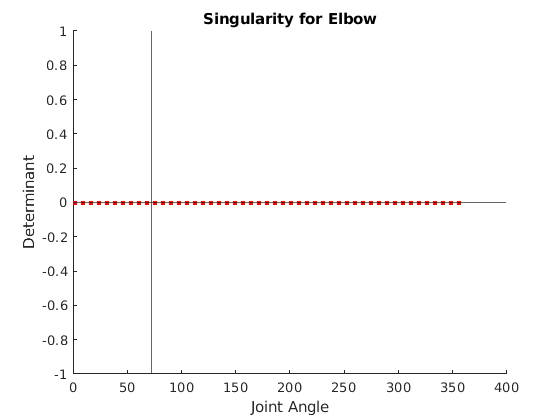


figure
title("Singularity for Elbow")
ylabel("Determinant")
xlabel("Joint Angle")
hold on;
plot(thetas, determinants, 'Color', 'r', 'LineStyle', ":", 'LineWidth', 3)
yline(0);
xline(72.43);
hold off;

### Functions

#### z_from_transform

Given a transformation, grab the z rotation column and return it as a matrix. This is useful for the Jacobian matrix calculations.

function z = z_from_transform(transform)
    z = transform(1:3, 3);
end

#### translation_from_transform

Given a transformation, isolate the translation column from it. This is useful for the Jacobian matrix calculations.

function o = translation_from_transform(transform)
    o = transform(1:3, 4);
end

#### transformations_from_dh_table

Given a DH table, move through each row and create a series of transformations back to the base (0th frame). This function returns a singular cell of each transformation relative to its frame transformation - where the i-th cell is the $H_i^0$ transformation.

function transforms = transforms_from_dh_table(dh_table, vargin)
    transforms = {};
    transform = 1;
    for row = 1:length(dh_table)
        if nargin == 2
            transforms{end+1} = simplify(transform * transform_from_dh_row(dh_table, row, true));
        else
            transforms{end+1} = transform * transform_from_dh_row(dh_table, row);
        end
        transform = transforms{end};
    end
end

#### jacobian_from_dh

Given a DH table, generate the Jacobian for that DH table. If an additional, second argument is passed if the DH table contains symbolic values, allowing us to do symbolic Jacobian generation instead of a numeric calculation. Extra steps are handled for symbolics - sin vs sind (radians over degrees) and routinely tries to simplify the Jacobian as it is generated.

function j = jacobian_from_dh_table(dh_table, vargin)
    if nargin == 2
        % Initialize our jacobian matrix
        j = sym(zeros(6, length(dh_table)));
        transforms = transforms_from_dh_table(dh_table, true);
    else
        % Initialize our jacobian matrix
        j = zeros(6, length(dh_table));
        transforms = transforms_from_dh_table(dh_table);
    end
    
    o_n = translation_from_transform(transforms{length(dh_table)});
    
    % Prep each row
    for row = 1:length(dh_table)
        row;
        if row == 1
           z_i = [0; 0; 1;];
        else
           transform = transforms{row-1}; 
           z_i = z_from_transform(transform);
        end
        
        if row == 1
           o_i = [0; 0; 0;]; 
        else
           transform = transforms{row-1};
           o_i = translation_from_transform(transform);
        end
        o_i;
        if nargin == 2
            j(1:3, row) = simplify(cross(z_i, o_n-o_i));
        else
            j(1:3, row) = cross(z_i, o_n-o_i);
        end
        cross(z_i, o_n-o_i);
        j(4:6, row) = z_i;
    end
end

#### transform_from_dh_values

This function takes the expected DH values - $\theta$, *d*, *a*, and $\alpha$. It then generates a transform for the given link.

The use of *vargin* is used to determine if an optional parameter is passed. This optional parameter is used to determine if the caller of the function wishes to make use of symbolic values. If so, we use *cos* and *sin* instead of *cosd *and *sind* respectively. This results in slightly better outputs for symbolic functions.

function H = transform_from_dh_values(theta, d, a, alpha, varargin)
    if nargin == 4
        R_z_theta = [ cosd(theta)      -sind(theta)     0     0;
                      sind(theta)       cosd(theta)     0     0;
                      0                 0               1     0;
                      0                 0               0     1; ];
        R_x_alpha = [ 1     0               0            0;
                      0     cosd(alpha)     -sind(alpha) 0;
                      0     sind(alpha)     cosd(alpha)  0;
                      0     0               0            1; ];
    else
        R_z_theta = [ cos(theta)      -sin(theta)     0     0;
                      sin(theta)       cos(theta)     0     0;
                      0                0              1     0;
                      0                0              0     1; ];
        R_x_alpha = [ 1     0              0            0;
                      0     cos(alpha)     -sin(alpha)  0;
                      0     sin(alpha)     cos(alpha)   0;
                      0     0              0            1; ];
    end
    
    
    T_z_d = [ 1     0      0    0;
              0     1      0    0;
              0     0      1    d;
              0     0      0    1; ];
    
    T_x_a = [ 1     0      0    a;
              0     1      0    0;
              0     0      1    0;
              0     0      0    1; ];
    
    
    
    H = R_z_theta * T_z_d * T_x_a * R_x_alpha;
end

#### transform_from_dh_row

This is a helper function that takes a DH table as defined above (in the form of a cell of matricies of expected DH values in a set standard order of $\theta$, *d*, *a*, and $\alpha$. It then separates out the $\theta$, *d*, *a*, and $\alpha$ of the specified row, and passes it to **transform_from_dh_values**, as described above. The use of *vargin* is passed through, for reasons specified above.

function H = transform_from_dh_row(table, row, vargin)
    theta = table{row}(1);
    d = table{row}(2);
    a = table{row}(3);
    alpha = table{row}(4);
    if nargin == 2
        H = transform_from_dh_values(theta, d, a, alpha);
    else
        H = transform_from_dh_values(theta, d, a, alpha, true);
    end
end